## 1 system

% find equilibrium points
syms x [2,1]
S = solve(system1(x) == 0);
ep = [S.x1 S.x2]

$$ep = \left(\begin{array}{cc} 0 & 0\\ 1 & -1\\ -1 & 1 \end{array}\right)$$

% find the eigenvalues of the matrix of the linearized system near each equilibrium point
jac = jacobian(system1(x), x)

$$jac = \left(\begin{array}{cc} 6\,{x_{1}}^{2}-1 & 1\\ -1 & -1 \end{array}\right)$$

for i = 1:size(ep, 1)
    A_lin = subs(jac, {x1, x2}, {ep(i,1), ep(i,2)});
    ev = eig(A_lin);
    
    fprintf('точка равновесия №%d\n', i)
    disp(ep(i,:))
    disp(A_lin)
    disp(round(ev,3))

end

точка равновесия №1


$$\left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cc} -1 & 1\\ -1 & -1 \end{array}\right)$$

$$\left(\begin{array}{c} -1.0-1.0\,\mathrm{i}\\ -1.0+1.0\,\mathrm{i} \end{array}\right)$$

точка равновесия №2


$$\left(\begin{array}{cc} 1 & -1 \end{array}\right)$$

$$\left(\begin{array}{cc} 5 & 1\\ -1 & -1 \end{array}\right)$$

$$\left(\begin{array}{c} -0.828\\ 4.828 \end{array}\right)$$

точка равновесия №3


$$\left(\begin{array}{cc} -1 & 1 \end{array}\right)$$

$$\left(\begin{array}{cc} 5 & 1\\ -1 & -1 \end{array}\right)$$

$$\left(\begin{array}{c} -0.828\\ 4.828 \end{array}\right)$$

1 - устойчивый фокус

2 - седловая точка

3 - седловая точка

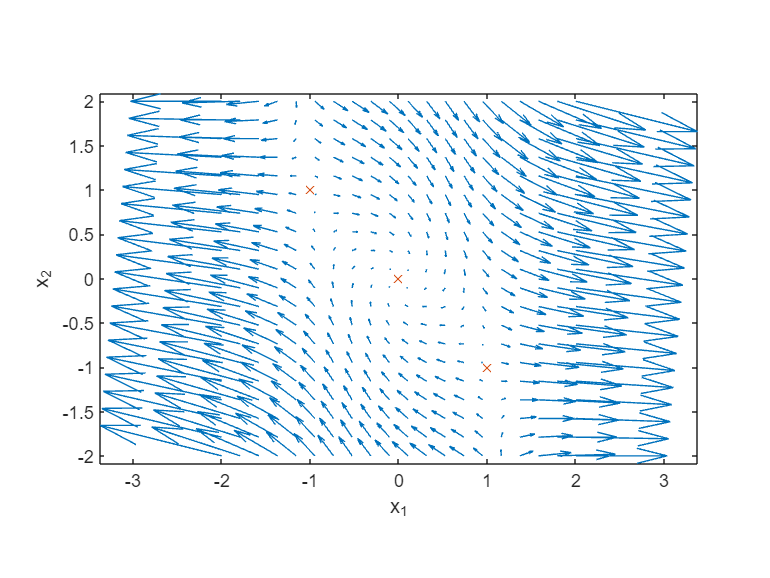

% phase plane
x_lim = [-2; 2];
y_lim = [-2; 2];
[x,y] = meshgrid(linspace(x_lim(1), x_lim(2), 20), linspace(y_lim(1), y_lim(2), 20));
u = zeros(size(x));
v = zeros(size(x));

for i = 1:numel(x)
    cur = system1([x(i); y(i)]);
    u(i) = cur(1);
    v(i) = cur(2);
end

quiver(x,y,u,v,5);
xlabel('x_1')
ylabel('x_2')
axis tight equal;

hold on
plot(ep(:,1),ep(:,2),'x')
hold off

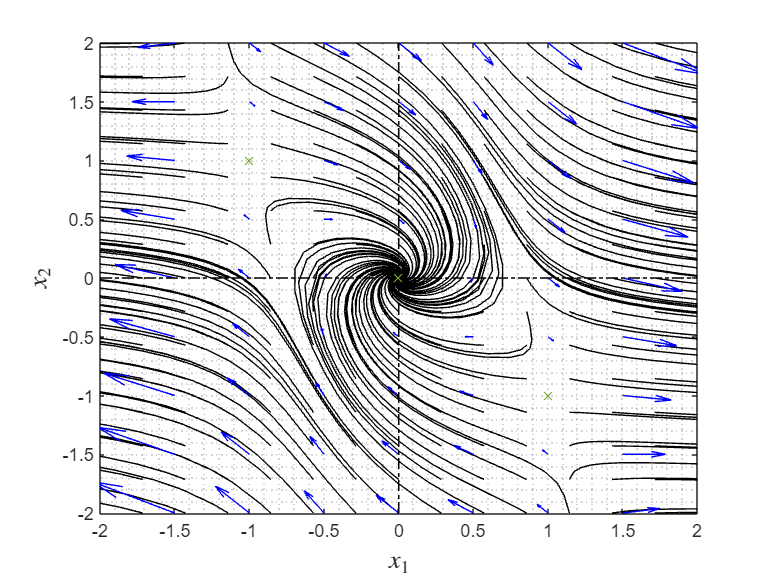

% phase portrait

tspan=[0,5];

[x_init,y_init] = meshgrid(linspace(x_lim(1), x_lim(2), 15), linspace(y_lim(1), y_lim(2), 15));
icond=cell(1,numel(x_init));
for n=1:numel(x_init)
    icond{n}=[x_init(n),y_init(n)];
end

figure;
warning('off')
PhasePlane(@system1,tspan,icond,'scale',2,'Xlim',x_lim,'Ylim',y_lim);
hold on
plot(ep(:,1),ep(:,2),'x')
hold off

## 2 system

% find equilibrium points
syms x [2,1]
S = solve(system2(x) == 0);
ep = [round(S.x1,3) round(S.x2,3)]

$$ep = \left(\begin{array}{cc} 0 & 0\\ 0 & 1.0\\ 1.0 & -1.0\\ -0.5-1.323\,\mathrm{i} & -1.0\\ -0.5+1.323\,\mathrm{i} & -1.0 \end{array}\right)$$

% find the eigenvalues of the matrix of the linearized system near each equilibrium point
jac = jacobian(system2(x), x)

$$jac = \left(\begin{array}{cc} x_{2}+1 & x_{1}\\ x_{2}-3\,{x_{1}}^{2} & x_{1}+2\,x_{2}-1 \end{array}\right)$$

for i = 1:size(ep, 1)
    A_lin = subs(jac, {x1, x2}, {ep(i,1), ep(i,2)});
    ev = eig(A_lin);
    
    fprintf('точка равновесия №%d\n', i)
    disp(ep(i,:))
    disp(A_lin)
    disp(round(ev,3))

end

точка равновесия №1


$$\left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cc} 1 & 0\\ 0 & -1 \end{array}\right)$$

$$\left(\begin{array}{c} -1.0\\ 1.0 \end{array}\right)$$

точка равновесия №2


$$\left(\begin{array}{cc} 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cc} 2 & 0\\ 1 & 1 \end{array}\right)$$

$$\left(\begin{array}{c} 1.0\\ 2.0 \end{array}\right)$$

точка равновесия №3


$$\left(\begin{array}{cc} 1 & -1 \end{array}\right)$$

$$\left(\begin{array}{cc} 0 & 1\\ -4 & -2 \end{array}\right)$$

$$\left(\begin{array}{c} -1.0-1.732\,\mathrm{i}\\ -1.0+1.732\,\mathrm{i} \end{array}\right)$$

точка равновесия №4


$$\left(\begin{array}{cc} -\frac{1}{2}-\frac{\sqrt{7}\,\mathrm{i}}{2} & -1 \end{array}\right)$$

$$\left(\begin{array}{cc} 0 & -\frac{1}{2}-\frac{\sqrt{7}\,\mathrm{i}}{2}\\ -3\,{\left(\frac{1}{2}+\frac{\sqrt{7}\,\mathrm{i}}{2}\right)}^{2}-1 & -\frac{7}{2}-\frac{\sqrt{7}\,\mathrm{i}}{2} \end{array}\right)$$

$$\left(\begin{array}{c} -1.829+1.432\,\mathrm{i}\\ -1.671-2.755\,\mathrm{i} \end{array}\right)$$

точка равновесия №5


$$\left(\begin{array}{cc} -\frac{1}{2}+\frac{\sqrt{7}\,\mathrm{i}}{2} & -1 \end{array}\right)$$

$$\left(\begin{array}{cc} 0 & -\frac{1}{2}+\frac{\sqrt{7}\,\mathrm{i}}{2}\\ -3\,{\left(-\frac{1}{2}+\frac{\sqrt{7}\,\mathrm{i}}{2}\right)}^{2}-1 & -\frac{7}{2}+\frac{\sqrt{7}\,\mathrm{i}}{2} \end{array}\right)$$

$$\left(\begin{array}{c} -1.829-1.432\,\mathrm{i}\\ -1.671+2.755\,\mathrm{i} \end{array}\right)$$

1 - седловая точка

2 - неустойчивый узел

3 - устойчивый фокус

4 - устойчивый фокус

5 - устойчивый фокус

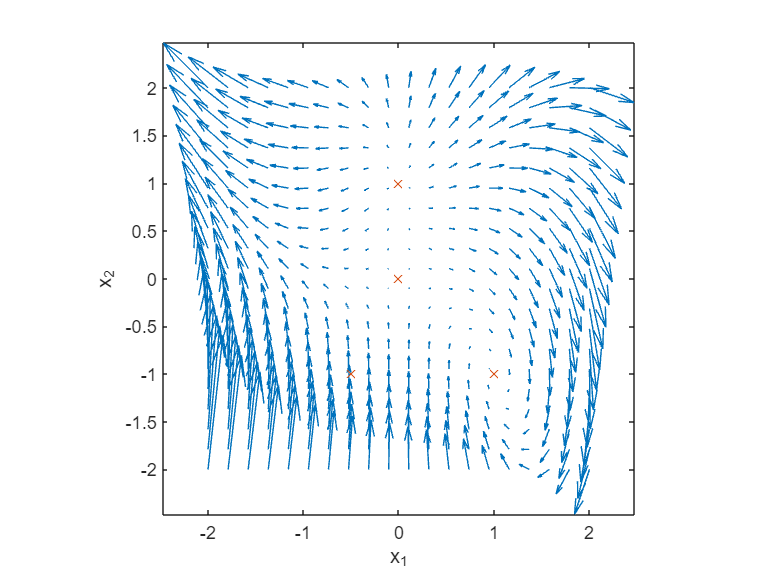

% phase plane
x_lim = [-2; 2];
y_lim = [-2; 2];
[x,y] = meshgrid(linspace(x_lim(1), x_lim(2), 20), linspace(y_lim(1), y_lim(2), 20));
u = zeros(size(x));
v = zeros(size(x));

for i = 1:numel(x)
    cur = system2([x(i); y(i)]);
    u(i) = cur(1);
    v(i) = cur(2);
end

quiver(x,y,u,v,5);
xlabel('x_1')
ylabel('x_2')
axis tight equal;

hold on
plot(ep(:,1),ep(:,2),'x')
hold off

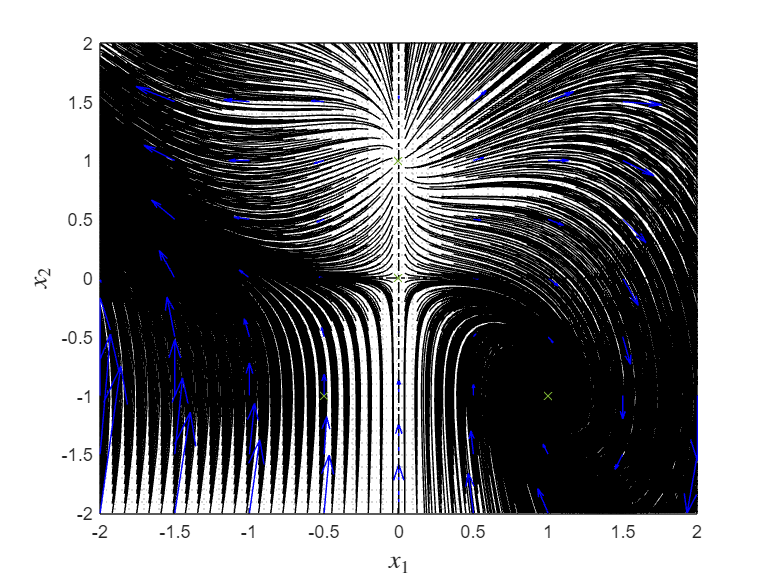

% phase portrait

tspan=[0,500];

[x_init,y_init] = meshgrid(linspace(x_lim(1), x_lim(2), 50), linspace(y_lim(1), y_lim(2), 50));
icond=cell(1,numel(x_init));
for n=1:numel(x_init)
    icond{n}=[x_init(n),y_init(n)];
end

figure;
warning('off')
PhasePlane(@system2,tspan,icond,'scale',2,'Xlim',x_lim,'Ylim',y_lim);
hold on
plot(ep(:,1),ep(:,2),'x')
hold off

## 3 system

% find equilibrium points
syms x [2,1]
S = solve(system3(x) == 0);
ep = [round(S.x1,3) round(S.x2,3)]

$$ep = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

% find the eigenvalues of the matrix of the linearized system near each equilibrium point
jac = jacobian(system3(x), x)

$$jac = \left(\begin{array}{cc} 0 & 1\\ -x_{2}\,\left(2\,x_{1}-\frac{2\,{x_{1}}^{3}}{5}\right)-1 & \frac{{x_{1}}^{4}}{10}-{x_{1}}^{2}+1 \end{array}\right)$$

for i = 1:size(ep, 1)
    A_lin = subs(jac, {x1, x2}, {ep(i,1), ep(i,2)});
    ev = eig(A_lin);
    
    fprintf('точка равновесия №%d\n', i)
    disp(ep(i,:))
    disp(A_lin)
    disp(round(ev,3))

end

точка равновесия №1


$$\left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cc} 0 & 1\\ -1 & 1 \end{array}\right)$$

$$\left(\begin{array}{c} 0.5-0.866\,\mathrm{i}\\ 0.5+0.866\,\mathrm{i} \end{array}\right)$$

1 - неустойчивый фокус

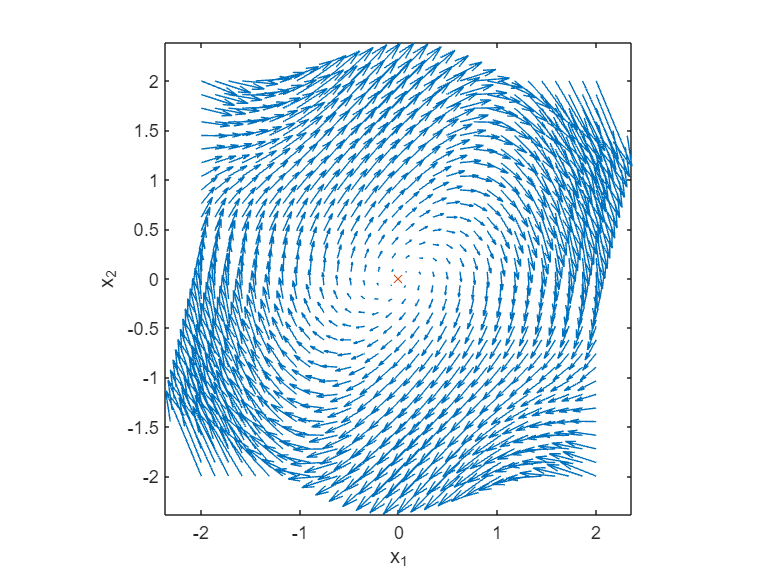

% phase plane
x_lim = [-2; 2];
y_lim = [-2; 2];
[x,y] = meshgrid(linspace(x_lim(1), x_lim(2), 30), linspace(y_lim(1), y_lim(2), 30));
u = zeros(size(x));
v = zeros(size(x));

for i = 1:numel(x)
    cur = system3([x(i); y(i)]);
    u(i) = cur(1);
    v(i) = cur(2);
end

quiver(x,y,u,v,5);
xlabel('x_1')
ylabel('x_2')
axis tight equal;

hold on
plot(ep(:,1),ep(:,2),'x')
hold off

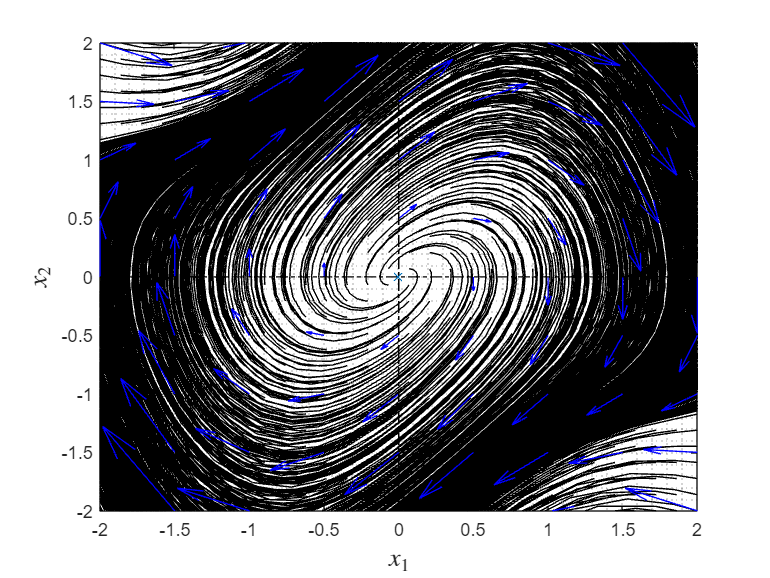

% phase portrait

tspan=[0,10];

[x_init,y_init] = meshgrid(linspace(x_lim(1), x_lim(2), 30), linspace(y_lim(1), y_lim(2), 30));
icond=cell(1,numel(x_init));
for n=1:numel(x_init)
    icond{n}=[x_init(n),y_init(n)];
end

figure;
warning('off')
PhasePlane(@system3,tspan,icond,'scale',2,'Xlim',x_lim,'Ylim',y_lim);
hold on
plot(ep(:,1),ep(:,2),'x')
hold off

наблюдаем неустойчивый предельный цикл

## 4 system

% find equilibrium points
syms x [2,1]
syms t1 t2
solve((t1-t2)*(1-t1^2-t2^2) == 0, t1)

$$ans = \left(\begin{array}{c} t_{2}\\ \sqrt{1-t_{2}}\,\sqrt{t_{2}+1}\\ -\sqrt{1-t_{2}}\,\sqrt{t_{2}+1} \end{array}\right)$$

solve((t1+t2)*(1-t1^2-t2^2) == 0, t2)

$$ans = \left(\begin{array}{c} \sqrt{1-t_{1}}\,\sqrt{t_{1}+1}\\ -t_{1}\\ -\sqrt{1-t_{1}}\,\sqrt{t_{1}+1} \end{array}\right)$$

S = solve(system4(x) == 0, x);
S.x1

$$ans = \left(\begin{array}{c} 0\\ -1\\ 1 \end{array}\right)$$

ep = [round(S.x1,3) round(S.x2,3)]

$$ep = \left(\begin{array}{cc} 0 & 0\\ -1.0 & 0\\ 1.0 & 0 \end{array}\right)$$

% find the eigenvalues of the matrix of the linearized system near each equilibrium point
jac = jacobian(system4(x), x)

$$jac = \left(\begin{array}{cc} 1-{x_{1}}^{2}-{x_{2}}^{2}-2\,x_{1}\,\left(x_{1}-x_{2}\right) & {x_{1}}^{2}-2\,x_{2}\,\left(x_{1}-x_{2}\right)+{x_{2}}^{2}-1\\ 1-{x_{1}}^{2}-{x_{2}}^{2}-2\,x_{1}\,\left(x_{1}+x_{2}\right) & 1-{x_{1}}^{2}-{x_{2}}^{2}-2\,x_{2}\,\left(x_{1}+x_{2}\right) \end{array}\right)$$

for i = 1:size(ep, 1)
    A_lin = subs(jac, {x1, x2}, {ep(i,1), ep(i,2)});
    ev = eig(A_lin);
    
    fprintf('точка равновесия №%d\n', i)
    disp(ep(i,:))
    disp(A_lin)
    disp(round(ev,3))

end

точка равновесия №1


$$\left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cc} 1 & -1\\ 1 & 1 \end{array}\right)$$

$$\left(\begin{array}{c} 1.0-1.0\,\mathrm{i}\\ 1.0+1.0\,\mathrm{i} \end{array}\right)$$

точка равновесия №2


$$\left(\begin{array}{cc} -1.0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cc} -2.0 & 0\\ -2.0 & 0 \end{array}\right)$$

$$\left(\begin{array}{c} -2.0\\ 0 \end{array}\right)$$

точка равновесия №3


$$\left(\begin{array}{cc} 1.0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cc} -2.0 & 0\\ -2.0 & 0 \end{array}\right)$$

$$\left(\begin{array}{c} -2.0\\ 0 \end{array}\right)$$

1 - неустойчивый фокус

2 - одно собственное значение = 0, значит будет либо седло, либо устойчивый узел

3 - одно собственное значение = 0, значит будет либо седло, либо устойчивый узел

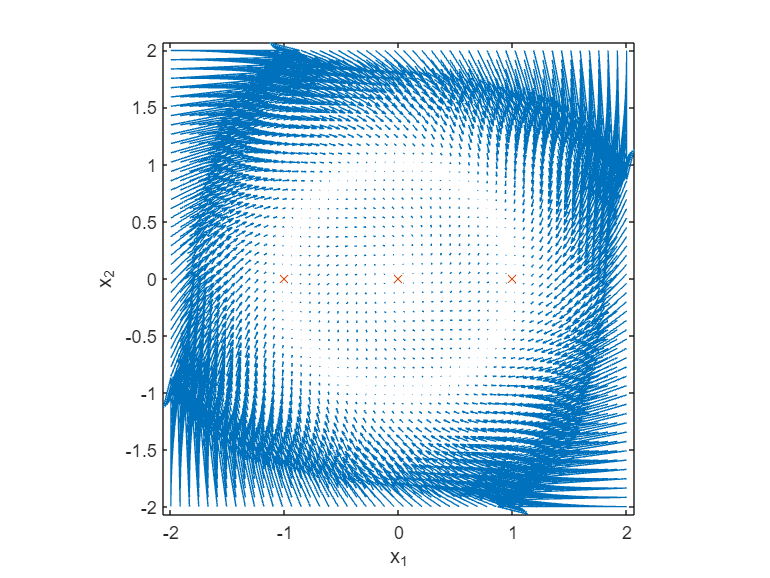

% phase plane
x_lim = [-2; 2];
y_lim = [-2; 2];
[x,y] = meshgrid(linspace(x_lim(1), x_lim(2), 50), linspace(y_lim(1), y_lim(2), 50));
u = zeros(size(x));
v = zeros(size(x));

for i = 1:numel(x)
    cur = system4([x(i); y(i)]);
    u(i) = cur(1);
    v(i) = cur(2);
end

quiver(x,y,u,v,10);
xlabel('x_1')
ylabel('x_2')
axis tight equal;

hold on
plot(ep(:,1),ep(:,2),'x')
hold off

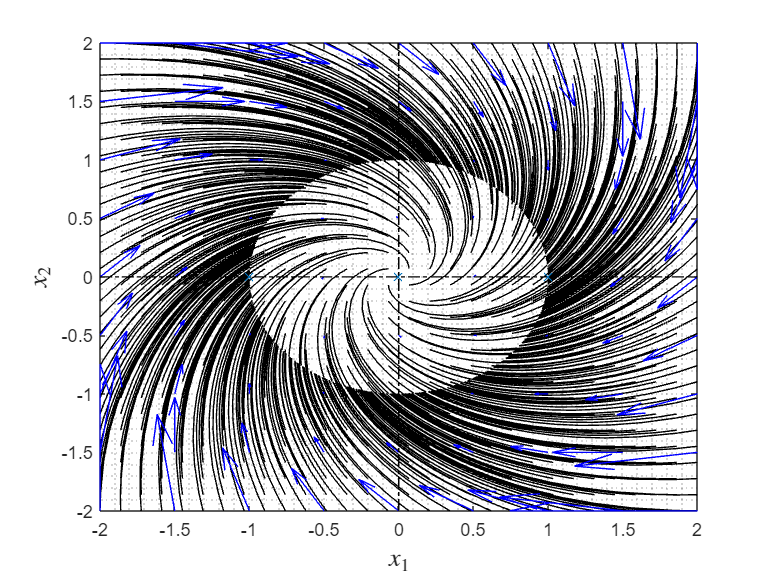

% phase portrait

tspan=[0,50];

[x_init,y_init] = meshgrid(linspace(x_lim(1), x_lim(2), 30), linspace(y_lim(1), y_lim(2), 30));
icond=cell(1,numel(x_init));
for n=1:numel(x_init)
    icond{n}=[x_init(n),y_init(n)];
end

figure;
warning('off')
PhasePlane(@system4,tspan,icond,'scale',2,'Xlim',x_lim,'Ylim',y_lim);
hold on
plot(ep(:,1),ep(:,2),'x')
hold off

так как в обоих уравнениях системы присутствует множитель (1-x1^2-x2^2), то вообще говоря мы имеем континуум точек равновесия на окружности радиуса 1. все точки равновесия на окружности имеют тип устойчивого узла.

## 5 system

% find equilibrium points
syms x [2,1]
S = solve(system5(x) == 0);
ep = [round(S.x1,3) round(S.x2,3)]

$$ep = \left(\begin{array}{cc} 0 & 0\\ -1.0 & -1.0\\ 1.0 & 1.0\\ 1.0\,\mathrm{i} & -1.0\,\mathrm{i}\\ -1.0\,\mathrm{i} & 1.0\,\mathrm{i}\\ 0.707-0.707\,\mathrm{i} & -0.707-0.707\,\mathrm{i}\\ 0.707+0.707\,\mathrm{i} & -0.707+0.707\,\mathrm{i}\\ -0.707-0.707\,\mathrm{i} & 0.707-0.707\,\mathrm{i}\\ -0.707+0.707\,\mathrm{i} & 0.707+0.707\,\mathrm{i} \end{array}\right)$$

% find the eigenvalues of the matrix of the linearized system near each equilibrium point
jac = jacobian(system5(x), x)

$$jac = \left(\begin{array}{cc} -3\,{x_{1}}^{2} & 1\\ 1 & -3\,{x_{2}}^{2} \end{array}\right)$$

for i = 1:size(ep, 1)
    A_lin = subs(jac, {x1, x2}, {ep(i,1), ep(i,2)});
    ev = eig(A_lin);
    
    fprintf('точка равновесия №%d\n', i)
    disp(ep(i,:))
    disp(A_lin)
    disp(round(ev,3))

end

точка равновесия №1


$$\left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cc} 0 & 1\\ 1 & 0 \end{array}\right)$$

$$\left(\begin{array}{c} -1.0\\ 1.0 \end{array}\right)$$

точка равновесия №2


$$\left(\begin{array}{cc} -1.0 & -1.0 \end{array}\right)$$

$$\left(\begin{array}{cc} -3.0 & 1\\ 1 & -3.0 \end{array}\right)$$

$$\left(\begin{array}{c} -2.0\\ -4.0 \end{array}\right)$$

точка равновесия №3


$$\left(\begin{array}{cc} 1.0 & 1.0 \end{array}\right)$$

$$\left(\begin{array}{cc} -3.0 & 1\\ 1 & -3.0 \end{array}\right)$$

$$\left(\begin{array}{c} -2.0\\ -4.0 \end{array}\right)$$

точка равновесия №4


$$\left(\begin{array}{cc} 1.0\,\mathrm{i} & -1.0\,\mathrm{i} \end{array}\right)$$

$$\left(\begin{array}{cc} 3.0 & 1\\ 1 & 3.0 \end{array}\right)$$

$$\left(\begin{array}{c} 4.0\\ 2.0 \end{array}\right)$$

точка равновесия №5


$$\left(\begin{array}{cc} -1.0\,\mathrm{i} & 1.0\,\mathrm{i} \end{array}\right)$$

$$\left(\begin{array}{cc} 3.0 & 1\\ 1 & 3.0 \end{array}\right)$$

$$\left(\begin{array}{c} 4.0\\ 2.0 \end{array}\right)$$

точка равновесия №6


$$\left(\begin{array}{cc} 0.707-0.707\,\mathrm{i} & -0.707-0.707\,\mathrm{i} \end{array}\right)$$

$$\left(\begin{array}{cc} 2.999094\,\mathrm{i} & 1\\ 1 & -2.999094\,\mathrm{i} \end{array}\right)$$

$$\left(\begin{array}{c} 2.827\,\mathrm{i}\\ -2.827\,\mathrm{i} \end{array}\right)$$

точка равновесия №7


$$\left(\begin{array}{cc} 0.707+0.707\,\mathrm{i} & -0.707+0.707\,\mathrm{i} \end{array}\right)$$

$$\left(\begin{array}{cc} -2.999094\,\mathrm{i} & 1\\ 1 & 2.999094\,\mathrm{i} \end{array}\right)$$

$$\left(\begin{array}{c} -2.827\,\mathrm{i}\\ 2.827\,\mathrm{i} \end{array}\right)$$

точка равновесия №8


$$\left(\begin{array}{cc} -0.707-0.707\,\mathrm{i} & 0.707-0.707\,\mathrm{i} \end{array}\right)$$

$$\left(\begin{array}{cc} -2.999094\,\mathrm{i} & 1\\ 1 & 2.999094\,\mathrm{i} \end{array}\right)$$

$$\left(\begin{array}{c} -2.827\,\mathrm{i}\\ 2.827\,\mathrm{i} \end{array}\right)$$

точка равновесия №9


$$\left(\begin{array}{cc} -0.707+0.707\,\mathrm{i} & 0.707+0.707\,\mathrm{i} \end{array}\right)$$

$$\left(\begin{array}{cc} 2.999094\,\mathrm{i} & 1\\ 1 & -2.999094\,\mathrm{i} \end{array}\right)$$

$$\left(\begin{array}{c} 2.827\,\mathrm{i}\\ -2.827\,\mathrm{i} \end{array}\right)$$

1 - седловая точка

2 - устойчивый узел

3 - устойчивый узел

4 - неустойчивый узел

5 - неустойчивый узел

6 - корни лежат на мнимой оси - фокусы

7 - корни лежат на мнимой оси - фокусы

8 - корни лежат на мнимой оси - фокусы

9 - корни лежат на мнимой оси - фокусы

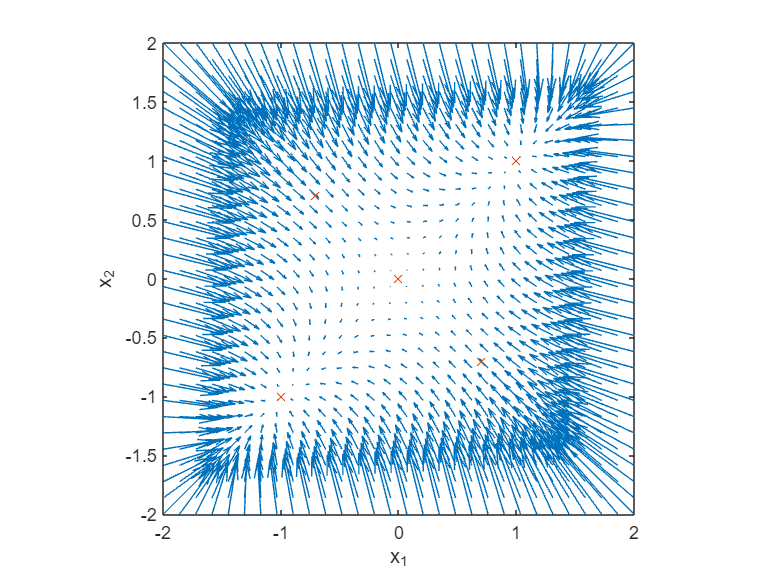

% phase plane
x_lim = [-2; 2];
y_lim = [-2; 2];
[x,y] = meshgrid(linspace(x_lim(1), x_lim(2), 30), linspace(y_lim(1), y_lim(2), 30));
u = zeros(size(x));
v = zeros(size(x));

for i = 1:numel(x)
    cur = system5([x(i); y(i)]);
    u(i) = cur(1);
    v(i) = cur(2);
end

quiver(x,y,u,v,5);
xlabel('x_1')
ylabel('x_2')
axis tight equal;

hold on
plot(ep(:,1),ep(:,2),'x')
hold off

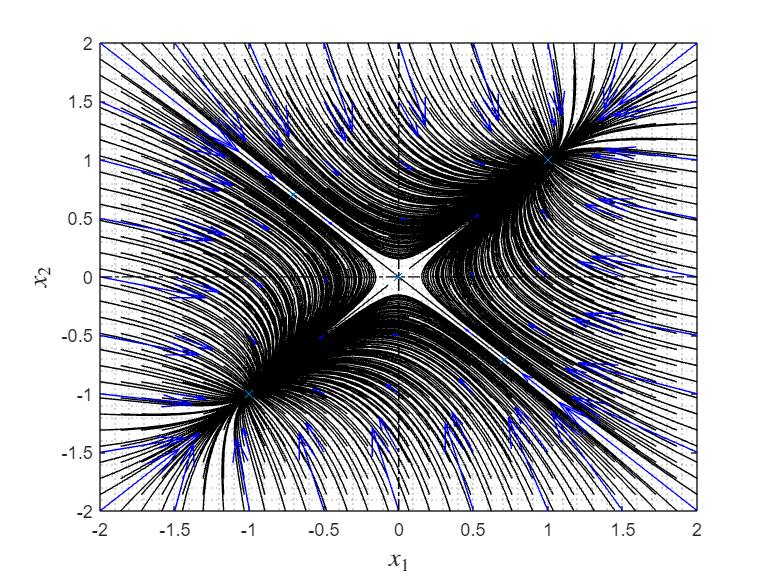

% phase portrait

tspan=[0,50];

[x_init,y_init] = meshgrid(linspace(x_lim(1), x_lim(2), 30), linspace(y_lim(1), y_lim(2), 30));
icond=cell(1,numel(x_init));
for n=1:numel(x_init)
    icond{n}=[x_init(n),y_init(n)];
end

figure;
warning('off')
PhasePlane(@system5,tspan,icond,'scale',2,'Xlim',x_lim,'Ylim',y_lim);
hold on
plot(ep(:,1),ep(:,2),'x')
hold off